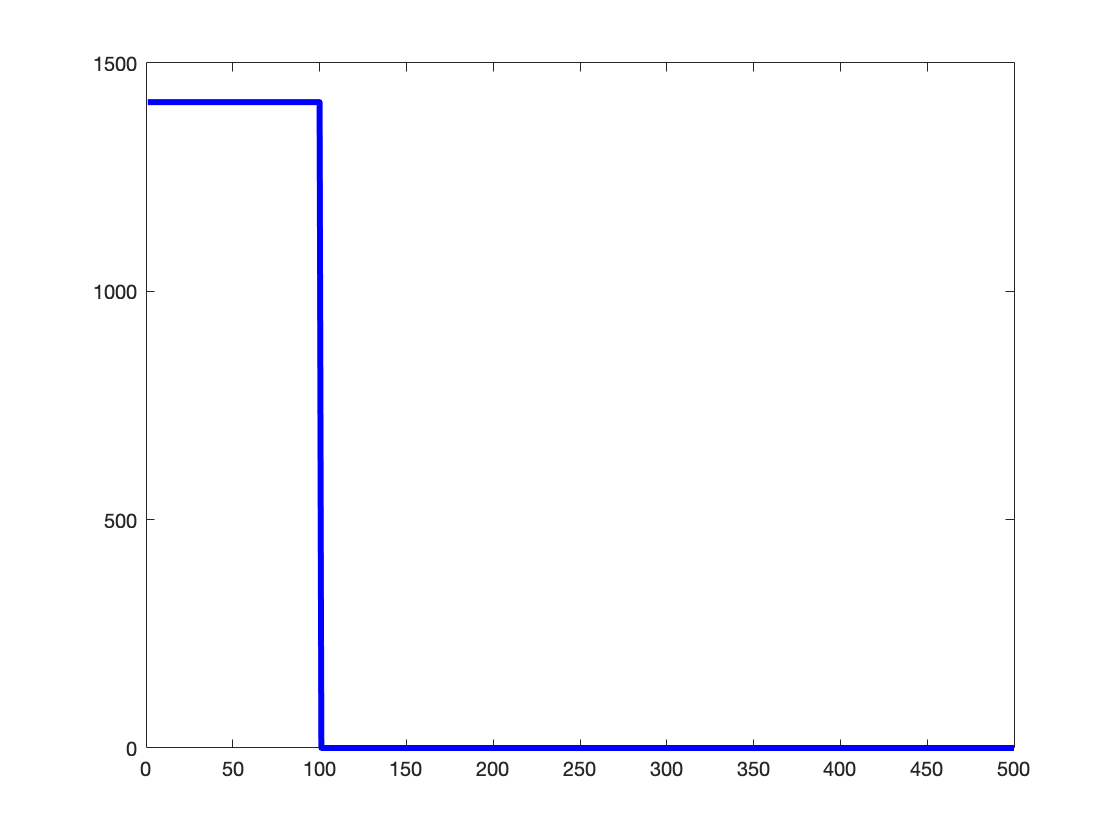

clear
close all

tau = 1e-6; %[s]
PRT = 5e-6; %repetition interval (PRI or PRT) - periodo [s]
fc = 5e6; %frequency [Hz]
Pt = 1e6; % Transmitted pulse peak power [dBW]
Loss = 70; %Signal losses [dB]
N = 5; %Number of pulses to plot
fs = 100e6; %Sampling frequency [Hz]
R = 0; %Distance to target [m]

dt = 1/fs;
Tfinal = N*PRT;
vt = 0:dt:Tfinal-dt; %vector starts from 0 
m = length(vt);

%How many samples fit in a single pulse?
N_tau = round(tau/dt);

%How many samples fit during the listening time?
N_PRT = round ((PRT-tau)/dt);


%Calculating the amplitude
A = sqrt(2*Pt);

v_a = [A*ones(1,N_tau) zeros(1,N_PRT)];

plot(v_a, 'b', "LineWidth",3)

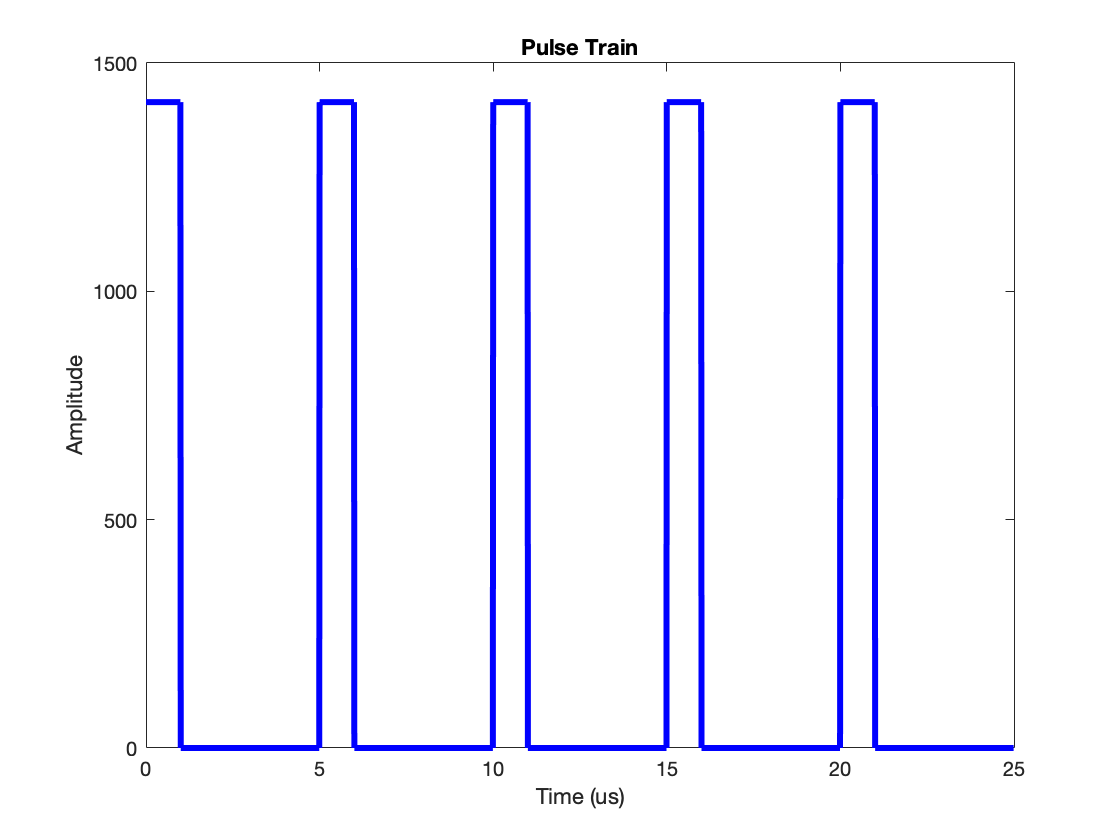


%Calculating the pulse train
v_all = [];

for i = 1:N
    v_all = [v_all v_a];
end


figure (1)
plot(vt*1e6, v_all, 'b', "LineWidth",3);
hold on
title("Pulse Train");
xlabel('Time (us)');
ylabel('Amplitude');

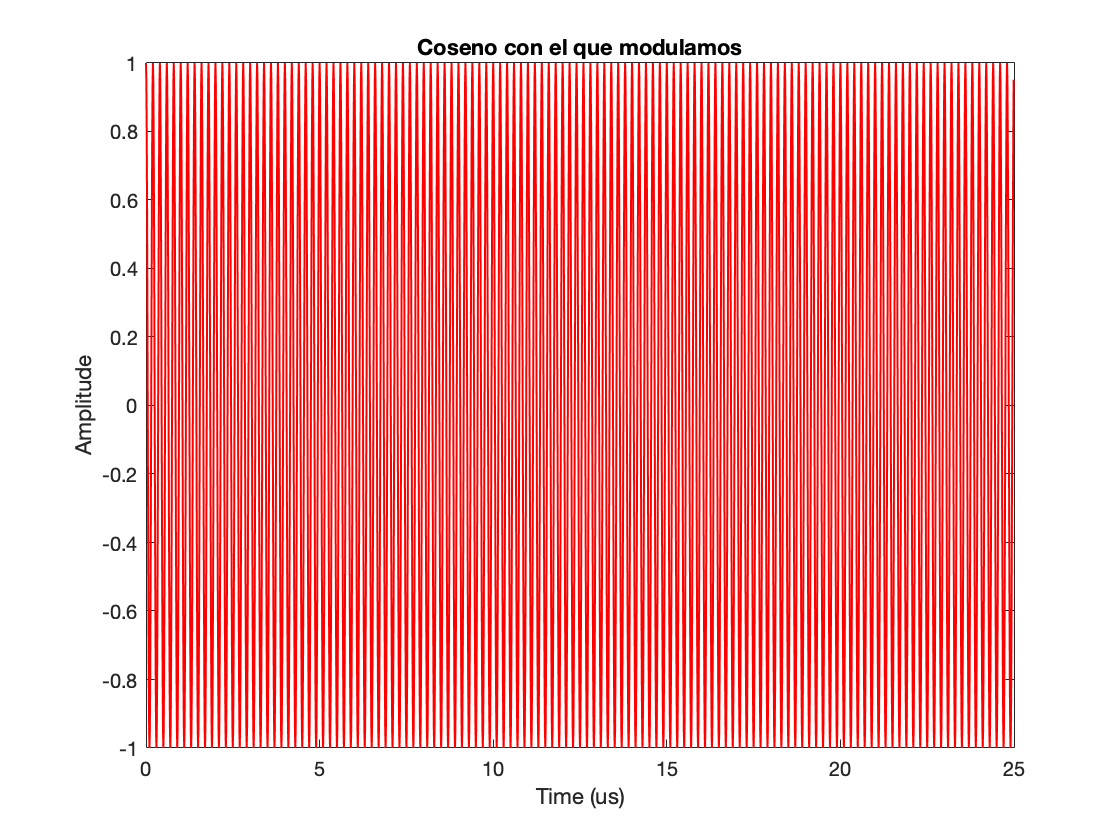



%Modulated signal
sc = cos(2*pi*fc*vt);

figure(2)
plot(vt*1e6,sc,'r',"LineWidth",1)
hold on
title("Coseno con el que modulamos");
xlabel('Time (us)');
ylabel('Amplitude');


sm = sc.*v_all;

hold on

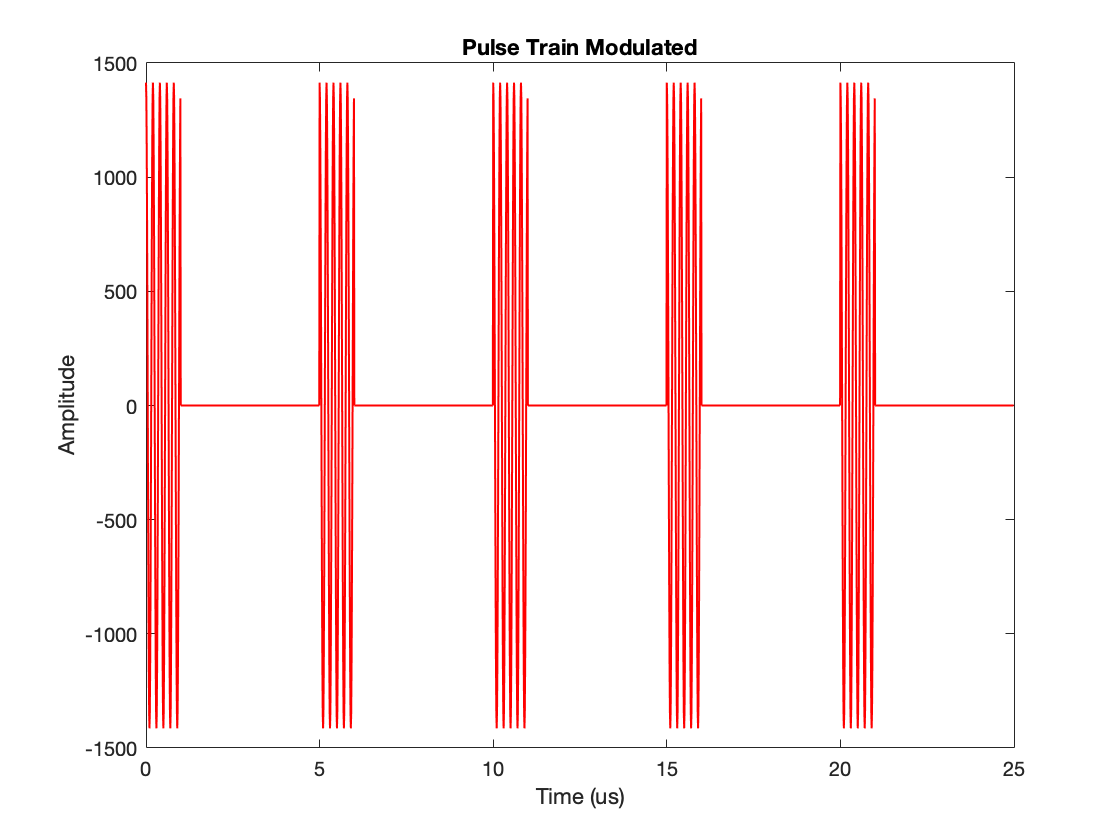

figure(3)
plot(vt*1e6,sm,'r',"LineWidth",1)
title("Pulse Train Modulated");
xlabel('Time (us)');
ylabel('Amplitude');
xlim([0 25]);
hold off

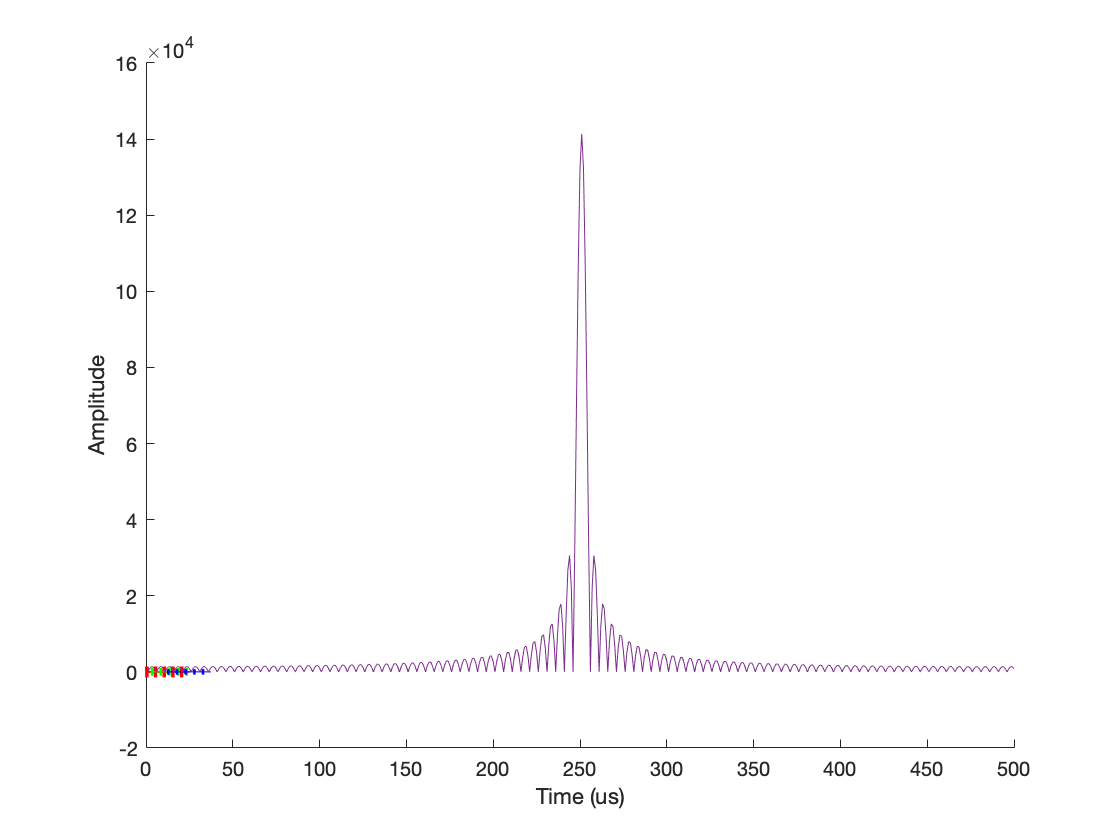


%ECO recieved signal
R_Target1 = 450;
R_Target2  =1*1852;  %NM to meters

c = 3e8;
T_Target1 = 2*R_Target1/c;
T_Target2 = 2*R_Target2/c;

figure(4)
hold on
plot(vt*1e6,sm,'r',"LineWidth",1);
plot((vt + T_Target1)*1e6, 1/sqrt(2)*sm,'g');
plot((vt + T_Target2)*1e6, 1/sqrt(4)*sm,'b');
xlabel('Time (us)');
ylabel('Amplitude');

Y = fftshift(abs(fft(v_a)));
plot(Y)